**Linear Epsilon-Support Vector Regression**

Apply the linear ε-SV regression model with ε = 0.5 to the training data given.

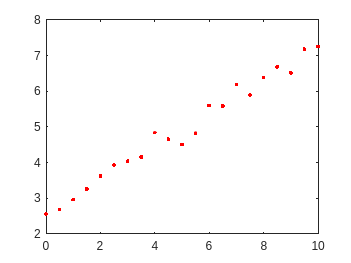

data = [0    2.5584
    0.5000    2.6882
    1.0000    2.9627
    1.5000    3.2608
    2.0000    3.6235
    2.5000    3.9376
    3.0000    4.0383
    3.5000    4.1570
    4.0000    4.8498
    4.5000    4.6561
    5.0000    4.5119
    5.5000    4.8346
    6.0000    5.6039
    6.5000    5.5890
    7.0000    6.1914
    7.5000    5.8966
    8.0000    6.3866
    8.5000    6.6909
    9.0000    6.5224
    9.5000    7.1803
   10.0000    7.2537];

x = data(:,1);
y = data(:,2);
l = length(x);
epsilon = 0.5;

plot(x,y,'r.');

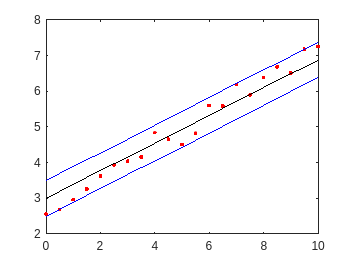

% Quadratic Values
Q = [1 0 
     0 0];

f = zeros(2,1);

D = [-x -ones(l,1)
      x  ones(l,1)];

d = epsilon*ones(2*l,1) + [-y;y];

% Solve the Quadratic Problem
options = optimset('LargeScale', 'off', 'Display','off');
solution = quadprog(Q,f,D,d,[],[],[],[],[],options);

% Compute w
w = solution(1);

% Compute b
b = solution(2);

% Plot the epsilon tube
u = w.*x + b; % Center line
v = w.*x + b + epsilon; % Up-line
vv = w.*x + b - epsilon; % Down-line

plot(x,y,'r.',x,u,'k-',x,v,'b-',x,vv,'b-');